# Soil Classification using Deep Learning

Classification of soils can be an important capability in many fields including geotechnical engineering, agricultural science, and construction. While many classification schemes exist, a popular and intuitive way of classifying soils is based on soil grain size, such as gravel, silt, sand, etc. This is a rather simple way of classifying soil because there are firm cutoffs between each classification. For example, gravel is any grain over 2 mm in diameter, sand is between 116 mm to 2 mm, and silt/clay is smaller than 116 mm. See [additional information on soil classification](https://apmonitor.com/pds/index.php/Main/SoilClassification).

Deep Learning (DL) is a subset of Machine Learning that uses Neural Network inspired architecture to make predictions. Convolutional Neural Networks (CNN) are a type of DL model that is effective in learning patterns in 2-dimensional data such as images. Images of soils are used to train a classifier to identify common soil types and fractions of soil type.

This exercise demonstrates the use of image classification to distinguish between soil types. Although applied to soil, the same methods and code can be used for any type or number of items. This example can be modified by including train and test photos in folders that are named with the item type. The code automatically takes the name of the folder as the photo label for training the classifier. Additional examples of image-based CNNs are found in the [**Bit and Crack Classification Case Study**](https://apmonitor.com/pds/index.php/Main/BitClassification).

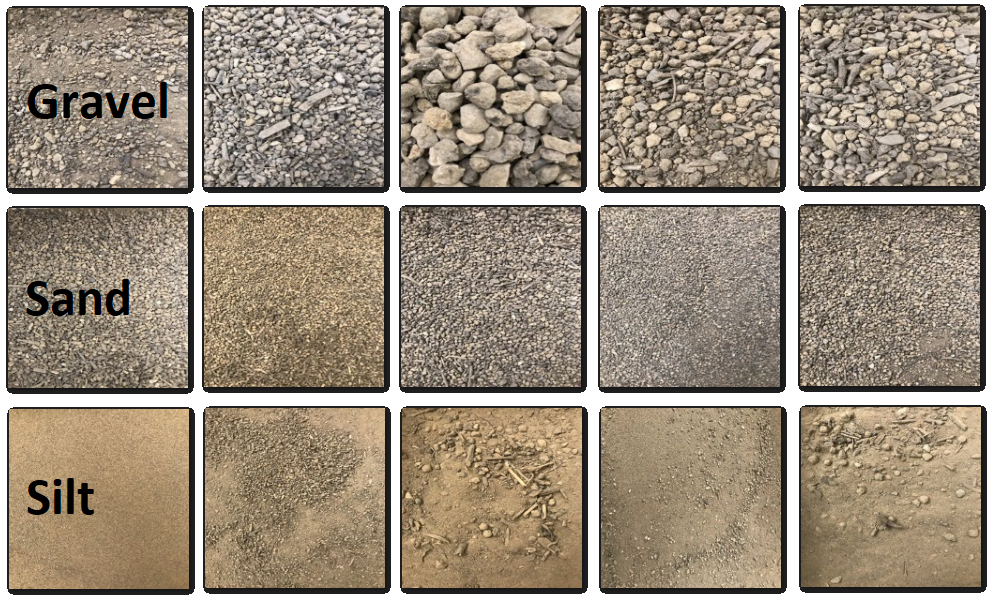

The archive contains two folders, a test folder and train folder with subdirectories corresponding to the possible soil types (Gravel, Sand, and Silt). The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───Gravel`

`  │   ├───Sand`

`  │   └───Silt`

`  └───train`

`      ├───Gravel`

`      ├───Sand`

`      └───Silt`

#### Objective

In this exercise, computer vision makes a classification model of soils based on photos of gravel, sand, and silt. A convolutional neural network framework is used classify photos of soil.

#### Key Concepts:Data Augmentation

Data Augmentation is a practice that is commonly used in image classification that enlarges the existing image dataset by creating new data sets from the existing data. This augmentation is most commonly seen in operations like shifting the image, mirroring the image horizontally or vertically, zooming in on the image, and so on. These augmentations then create new images and thus enhance the number of images to train on. Read more about this in an [article from Jason Brownlee](https://machinelearningmastery.com/how-to-configure-image-data-augmentation-when-training-deep-learning-neural-networks/).

#### Convolutional Neural Network (CNN)

A convolutional neural network (CNN) is a popular model for image classification. CNNs distinguish characteristics of an image by looping through the pixel values in an image and calculating the dot product of a those pixels with a filter `kernel` matrix. These kernel matrices accentuate different aspects of the image such as vertical and horizontal lines, curvature, etc. For more information on CNNs, see [APMonitor - Computer Vision with Deep Learning](https://apmonitor.com/pds/index.php/Main/VisionDeepLearning).

training_data_directory = 'train';
test_data_directory = 'test';

#### Data

The data is separated into directories test and train. The test folder and train folder contain subdirectories corresponding to the possible soils. The labeled tree structure of the folders assists with marking the photos for training and testing.

% Download the file
url = 'http://apmonitor.com/pds/uploads/Main/soil_photos.zip';
filename = 'soil_photos.zip';
outfilename = websave(filename,url);

% Unzip then deleate zip folder
unziped_folder = unzip(filename);
delete(filename);

Import the data into the Matlab live editor. The first step is to process the images into a format that 1) makes the data readable to the model, and 2) provides more training material for the model to learn from. For example, the `train_processor` variable scales the data so that it can be a model input, but also takes each image and augments it so that the model can learn from multiple variations of the same picture. It flips it horizontally, rotates it, shifts it, and more so that the model learns from the soil photo rather than the orientation or size.

augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1]);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [.8 1.2]);

% Load data
train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess = augmentedImageDatastore([255,255],train);

#### Model Building

Build the CNN model. The following cell sets parameters for model building. This includes the number of convolutional layers, fully connected dense layers, the number of nodes in each layer, and the number of training epochs. For more information on these parameters and Convolutional Neural Networks in general, see [APMonitor - Computer Vision with Deep Learning](https://apmonitor.com/pds/index.php/Main/VisionDeepLearning). The `layer_size` parameter has a large influence on the training speed, accuracy, and size of the model.

num_conv_layers = 3;
num_dense_layers = 2;
layer_size = 20;
num_training_epochs = 20;

layers = [
    imageInputLayer([255 255 3])
    convolution2dLayer([3 3],layer_size,"Padding","same")
    reluLayer()
    maxPooling2dLayer([2 2],"Padding","same")];

% Add additional convolutional layers based on num_conv_layers
for i = 1:num_conv_layers-1
    layers = [layers
              convolution2dLayer([3 3],layer_size,"Padding","same")
              reluLayer()
              maxPooling2dLayer([2 2],"Padding","same")];
end
layers = [layers
          flattenLayer()];
for i = 1:num_dense_layers
    layers = [layers
              fullyConnectedLayer(layer_size)
              reluLayer()];
end
layers = [layers
          fullyConnectedLayer(3)
          softmaxLayer()
          classificationLayer()];

options = trainingOptions("adam", ...
    InitialLearnRate=0.01, ...
    SquaredGradientDecayFactor=0.99, ...
    MaxEpochs=num_training_epochs, ...
    MiniBatchSize=32, ...
    Verbose=true,...
    Plots="training-progress");

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |        0.00% |       7.6867 |          0.0100 |
|       2 |          50 |       00:03:08 |       68.75% |       0.8853 |          0.0100 |
|       4 |         100 |       00:06:10 |       78.12% |       0.7737 |          0.0100 |
|       5 |         150 |       00:09:26 |       71.88% |       0.8101 |          0.0100 |
|       7 |         200 |       00:12:50 |       84.38% |       0.5535 |          0.0100 |
|       8 |         250 |       00:16:29 |       68.75% |       0.6489 |          0.0100 |
|      10 |         300 |  

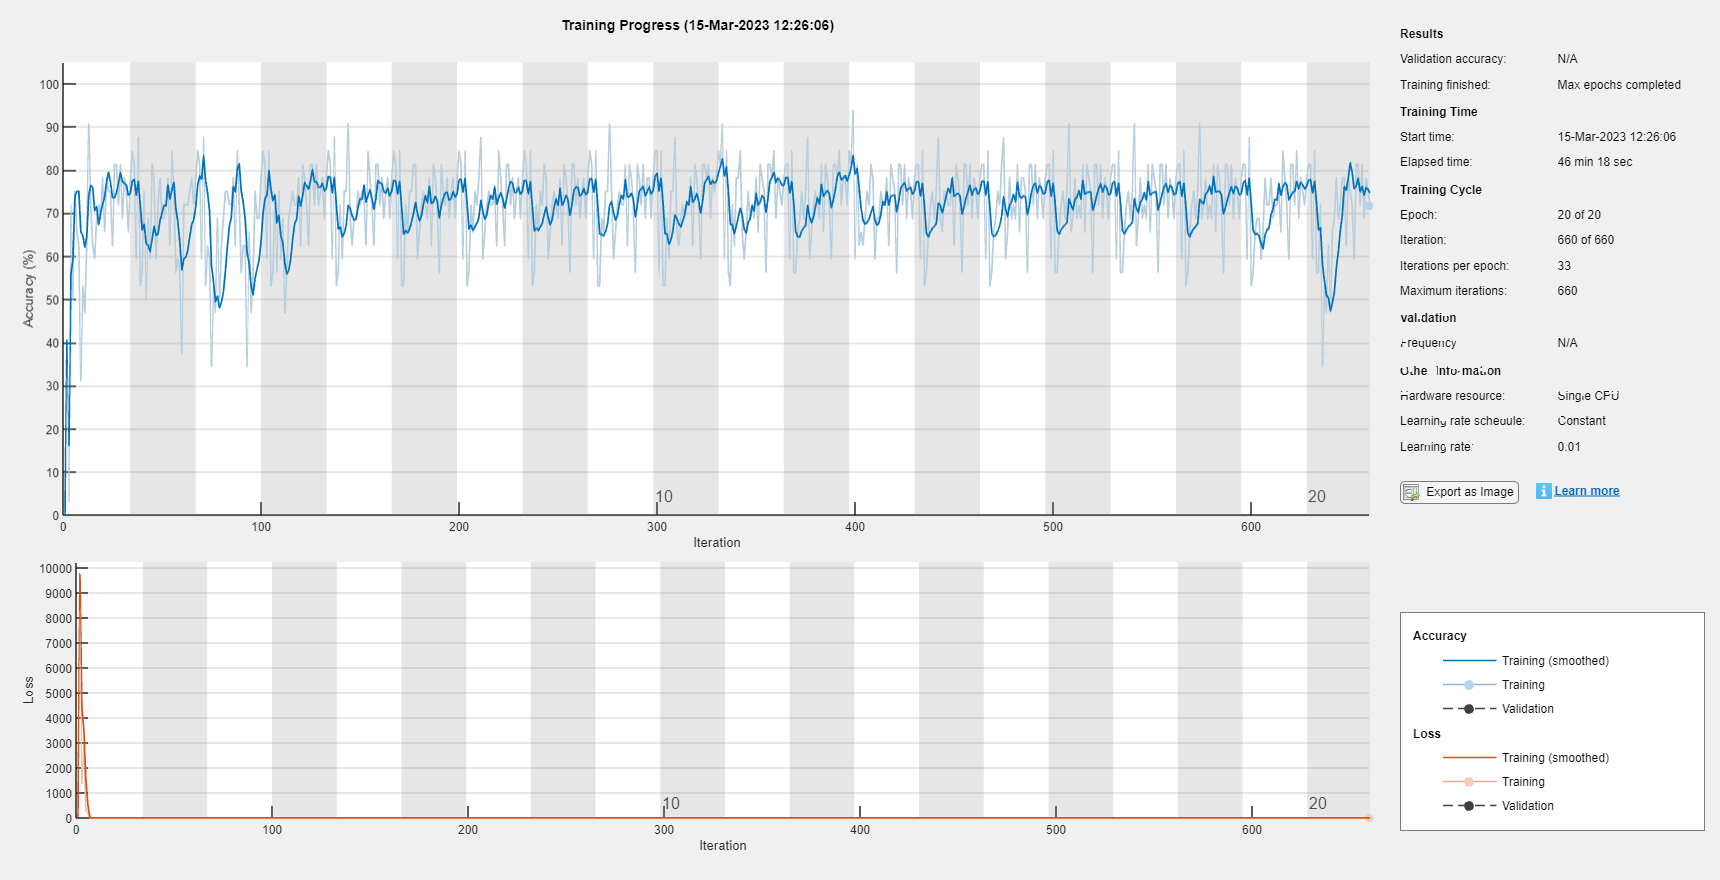

[net,info] = trainNetwork(train_preprocess, layers, options);

#### `Model Testing`

The model has now been trained and has been saved to the computer (in the same folder as this script). The last line of the printed output above contains the accuracy for both the training data and the validation, or testing data. Pay attention to the `val_accuracy` value on the last line, which corresponds to the accuracy on images that the model was not trained on. This is the best measure of the estimator performance on other images.

The following function, `make_prediction`, takes the file path to a soil photo as an input and outputs the classification that the model predicted. From the test folder, copy the filepath into the test_image_filepath variable in the second cell. Try out a few photos and see how the model preforms.

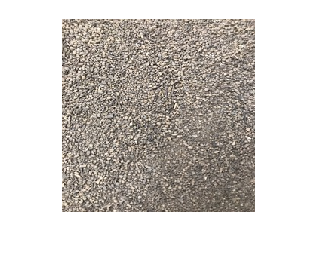

btype = ["Gravel", "Sand", "Silt"]; % possible output values
rng('shuffle');
i=randi(2);
j=randi([0,5]);
b = btype(i);
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

image_fp = test_image_filepath;
ime = imread(image_fp); % load image
imshow(ime);


im = double(imresize(ime,[255 255]));
image_array = im / 255.0; % scale the image
img_batch = reshape(image_array, [size(image_array)]);

predicted_value = net.classify(im)

predicted_value = categorical
     Positive 


true_value = regexp(image_fp, "(Gravel)|(Sand)|(Silt)", 'match');
true_value = true_value{1}

true_value = 'Sand'

#### Soil Classification Percentages

Soils are not perfectly homogenous (all one soil type). Soils are often a blend of types and may be better represented using a percentage. For example, the cell below shows a test photo that is labeled "Silt":

% Put code here

This photo has some gravel, however, there appears to be sand, gravel, and silt all in one photo. In order to better classify this image, create a proportion of each label. For example, this photo might be 30% Gravel, 20% Sand, and 50% Silt.

Subdivide the photo into many smaller segments or squares and train a classifier on the smaller squares. Loop through the photo to classify each small square and take a proportion of the squares pertaining to Gravel, Sand, and Silt. This proportion is then converted into a percentage of the respective soil type.

#### Data

Run these cells below to subdivide the existing training photos into smaller segments. The new directory will be called train_divided and test_divided.

Note: This will take time (~30 seconds to 2 minutes)

% Put code here

#### Load Model

If the number of input pixels changes, a new model should be trained or the image rescaled to the original training dimensions. For the purposes of this demo, retraining is not needed because the photos are upscaled to 1024x1024 before subsampling 256x256 blocks (16) in each image.

#### Classify Image

Use the loaded model to classify a test image. The function `classify_images` takes an image and a model and loops through each 256x256 square. It classifies each square and adds to the counter to create the fractional soil prediction. The function outputs the proportion of each soil type that was classified.

Does the percentage classified match the photo?

Both approaches to soil classification have advantages. For example, classifying the entire image is faster. However, percentage classification is more computationally expensive but provides more information and may be a better representation of the true classification.